# Sending Men on The Moon

[⇦ Overview](matlab:open('./Overview.m'))

 [Insert Emma's drawing of rocket to the Moon]

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

`Icon that can be used`

  **Try**.   **Pro-tip**. ** Demonstration**.  **Reflect**. ** Application.**

## Introduction

### The Apollo 11 Mission

From 1961 to 1972, NASA developped a space exploration program named Apollo which principal objective was to be the first space agency to explore the Moon. In 1969, the Apollo 11 mission successfully launch from Cape Canaveral, Florida using a Saturn V rocket. After a couple of revolution around the earth, the spacecraft occupied by astronauts Neil Armstrong, Michael Collins and Buzz Aldrin left earth orbit in direction of the Moon. After achieving the first lunar landing, astronaut Neil Armstron and Buzz Aldrin were the first men to ever set foot on the Moon. Twenty-one hours later, the crew took off from the Moon to rendez-vous with Michael Collins who stayed in orbit before to safely return home.

### The Saturn V Rocket

IntroRocket()

## Modelling the launch

In this script, we will apply the integral form of the mass conservation equation and the linear momentum conservation equation to the Saturn V rocket. Our goal here, is to **model the first phase of Apollo 11's launch**. The results from this model should be able to give us the altitude of rocket with respect to time during this acent phase. As first step towards that goal, we are making the following assumption:

- The friction forces along the rocket are negligible compare to the thrust generated by the rockets engines.

- The flight path of the rocket during the first phase is the ascent is purely vertical

### Define Control Volume

The first step of every problem using the integral form of mass and momentum conservation equations is to define the control volume and control surfaces consider for the problem. In the case of the rocket, we are chosing a movin control volume, that is the the rocket.

  **Try**. Use the followin drop down menu to visualize the Control Volume and associated Control Surfaces of the domain.

Item = 3;
IntroControlVolume(Item)

Solving the mass and momentum conservation equation often involved integration of mass and momentum fluxes through the Control Surfaces. One of the main sources of error in solving this kind of problem come from a poor definition of the normal vector to the Control Surfaces.

  **Try**. Define the direction of the normal vector to the bottom Control Surface of the Control Volume that we just defined.

Direction = 2;
ScoreT1 = SelectDirectionBottomControlSurface(Direction);

  **Try**. Now that you correctly defined the normal to the bottom Control Volume, try using the following drop-down menu to visualize the normal vector of the other Control Surfaces.

CV = "CSB";
figure()
DrawSaturn(CV, "dS");
xlim([-80 80])
ylim([-22 115])

### Apply Conservation of Mass

Now the Control Volume and the Control Surfaces were defined, we can start applying conservation law. The Mass Conservation equation is often time the first one to be applied to fluid dynamics problem, mainly because its constituing terms are usually simpler to compute than the one present in the conservation of momentum and energy. Remember that the mass conservation equation applied to a Control Volume is as follow:


$$\frac{\partial}{\partial t}\int_{CV}\rho dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho dS = 0$$


In the case of the the domain that we defined in the previous section, the mass flux integral over the Control Surfaces can be broken down into three integral over the right, left and bottom Control Surfaces:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho dV}_\text{A}
+
\underbrace{\int_{CS_{right}} ({\bf u}\cdot{\bf n})\rho dS }_\text{B}
+
\underbrace{\int_{CS_{left}} ({\bf u}\cdot{\bf n})\rho dS }_\text{C}
+
\underbrace{\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS }_\text{D}
= 0$$


  **Pro-tip**. In most fluid dynamics problem, the first step towards solving the problem consists in simplifying the equation rather than actually performing the integration. In the case of the Mass Conservation equation, we should be looking for the negligible or null mass flux.

  **Try**. Which one of the term in equation (XXX) is null?

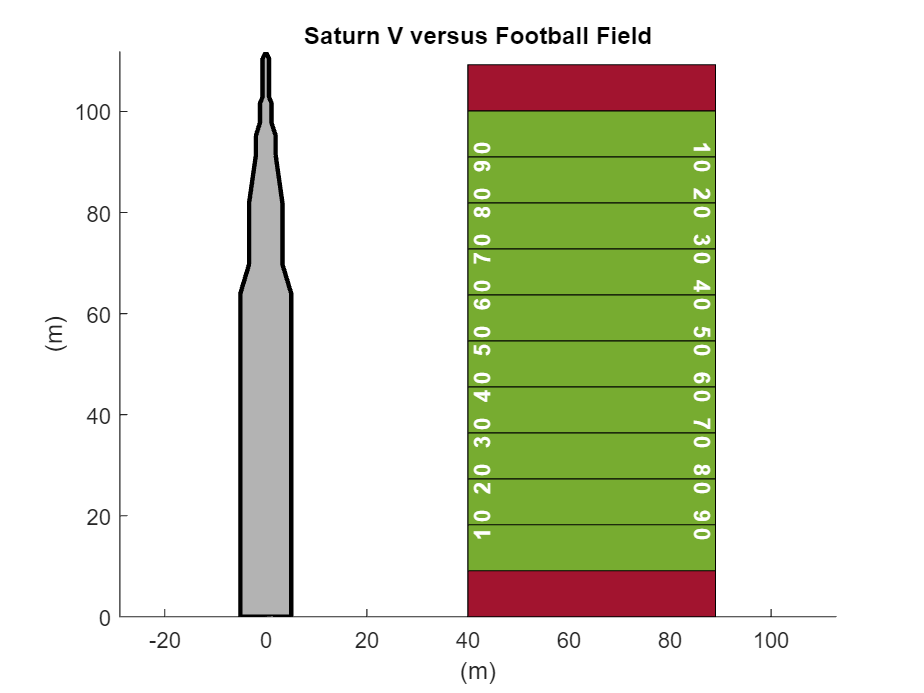

A = false; B = true; C = true; D = false;
 
if (~A & B & C & ~D)
    disp("All good!")
else

    warning("There is at least one wrong answer, try again!")
end

That being done, we can start developping the other term in the equation (XXX), starting with term A.

  **Try**. What is term A equal to?


$$\text{1) } \frac{\partial m(t)}{\partial t} 
\quad\quad
\text{2) } {\bf u}\cdot \frac{\partial m(t)}{\partial t}
\quad \quad
\text{3) } u_e \frac{\partial m(t)}{\partial t}
\quad \quad
\text{4) } \frac{\partial m(t)\times t}{\partial t}$$


A = 1;
if A == 1
    disp("All good!")
else
    warning("Wrong answer, try again!")
end

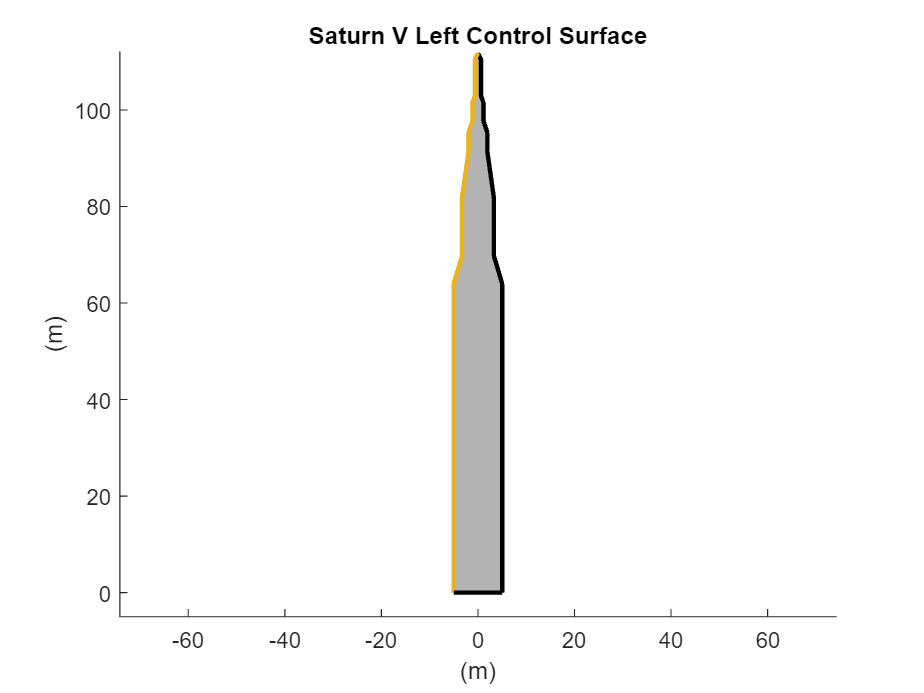

figure()

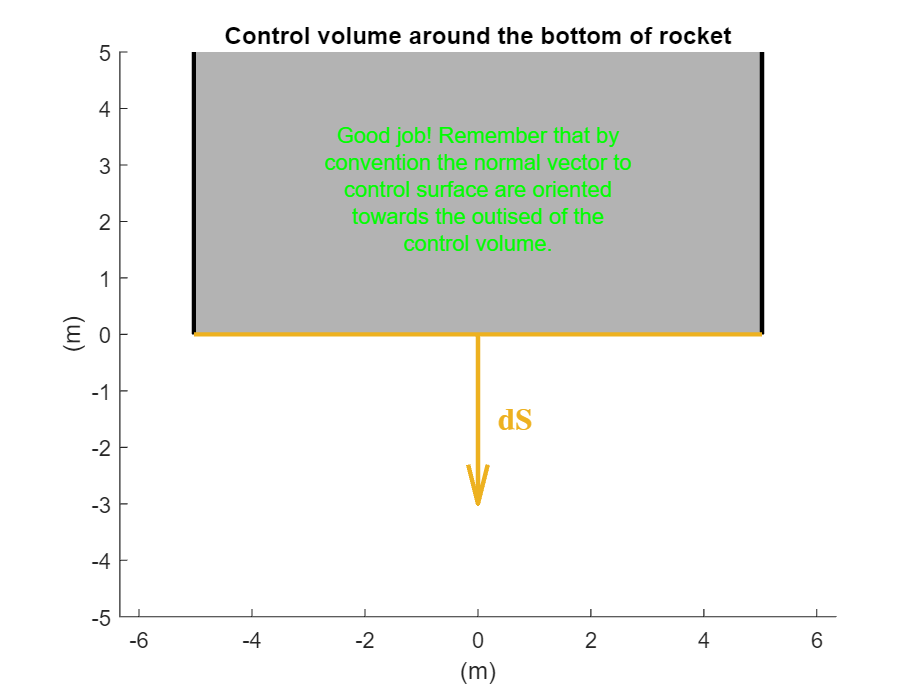

ax = DrawSaturn("CSB");
ylim([-5 5])
hold on
quiver(0,0,0,-3,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(3,:))
text(0.2,-1.5,"${\bf n}$", "Interpreter","latex", "FontSize",14, "Color",ax.ColorOrder(3,:))

for i = 1:4
    quiver(i,0,0,-2,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(1,:))
    quiver(-i,0,0,-2,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(1,:))
end
text(4.2, -1.0, "${\bf u}=-u_e\cdot{\bf e_y}$", "Interpreter","latex", "FontSize",14, "Color",ax.ColorOrder(1,:))
hold off

  **Try**. Which one of this assumption is true?


$$\text{1) }{\bf u}\cdot{\bf n} = -u_e
\quad\quad
\text{2) }{\bf u}\cdot{\bf n} = u_e$$


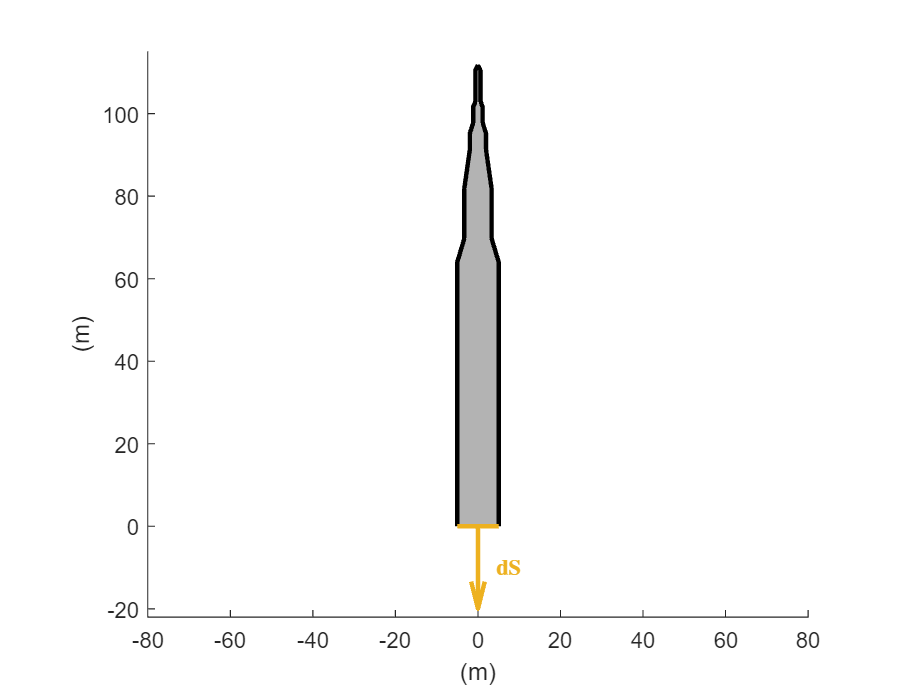

Q = 1;

Q = Q == 2;
if Q
    disp("Yes, 2 is the right answer!")
else
    warning("The answer to this question is wrong")
end

figure()
ax = DrawSaturn("CSB");
ylim([-5 5])
hold on
quiver(0,0,0,-3,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(3,:))
text(0.2,-2.3,"${\bf n}$", "Interpreter","latex", "FontSize",14, "Color",ax.ColorOrder(3,:))
for i = 1:4
    quiver(i,0,0,-2,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(1,:))
    quiver(-i,0,0,-2,0,"AutoScale","off","LineWidth",2,"MaxHeadSize",0.7, "Color",ax.ColorOrder(1,:))

All good!


end
text(4.2, -1.0, "${\bf u}$", "Interpreter","latex", "FontSize",14, "Color",ax.ColorOrder(1,:))
patch([-5 5 5 -5], [-2 -2 0 0], ax.ColorOrder(1,:), "FaceAlpha", 0.2, "LineStyle", "none")
line([-5 -5 5 5], [0 -2 -2 0], "Color",ax.ColorOrder(1,:), "LineStyle", "--", "LineWidth", 2)
hold off

In the previous figure, the highlighted area represent the value of the remaining integral in the Mass Conservation equation:


$$\frac{\partial m(t)}{\partial t}
+\int_{CS_{bottom}} \rho u_e dS
= 0$$


  **Try**. What is the value of the remaining integral in equation (XXX)?


$$\text{1) } {\bf u}\cdot\dot{m_e}
\quad\quad
\text{2) } -u_e\dot{m_e} 
\quad\quad
\text{3) } \dot{m_e}
$$


Q = 3;
Q = Q == 3;
if Q
    disp("Yes, 3 is the right answer!")
else

All good!


    warning("The answer to this question is wrong")
end

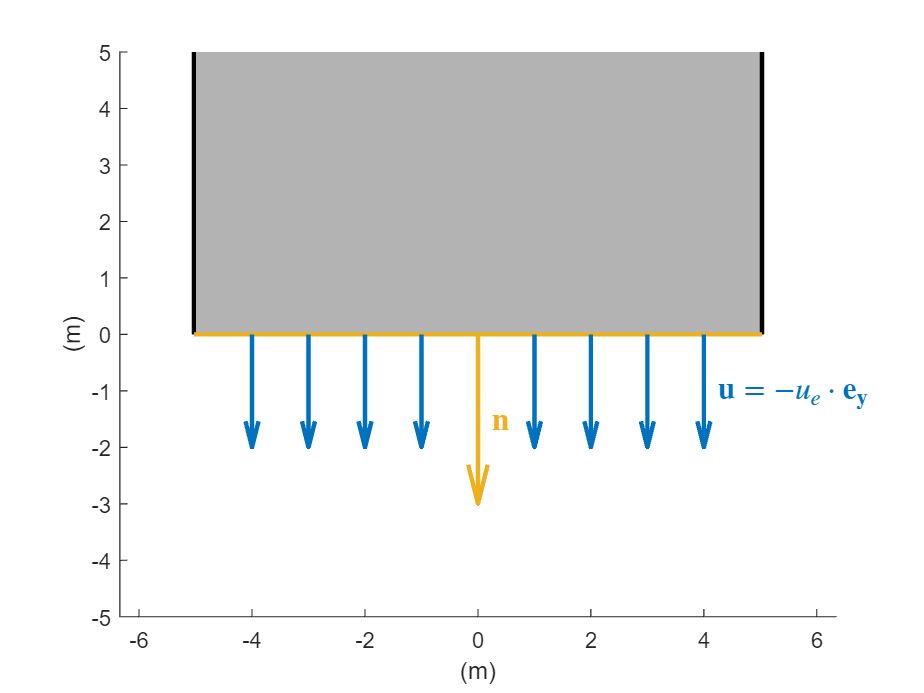

figure()
DrawSaturn("CSB");
ylim([-5 5])
title("Control volume around the bottom of rocket")
hold on
for i = -5:5
    q = quiver(i,0,0,-3,0,"filled", "LineWidth", 2, "SeriesIndex", 1, "AutoScale", "off", "MaxHeadSize", 1.5);
end
text(0.0,-3.8, "$\dot{m_e}$", "Interpreter","latex", "FontSize",14, "Color", q.Color, "HorizontalAlignment","center")
text(0,2, "$m(t)$", "Interpreter","latex", "FontSize",14, "Color", "k", "HorizontalAlignment","center")
hold off

The final differential equation obtained from the mass conservation equation is the following: 


$$\frac{\partial m(t)}{\partial t} = -\dot{m_e}$$


The solution of the differential is of the form: $m(t) = -\dot{m_e}   t + C$

We can define a value of the constant integration $C$by considering the initial mass of the rocket $m_0$ at $t = 0
$.


$$m(t) = m_0 - \dot{m_e}t$$


In the case of the Saturn V rocket for the Apollo 11 mission, the initial mass of the rocket was 2,950,000 kg and the total mass flow out of the five F-1 engine totaled at 12,600 kg/s.

t = linspace(0,161,2);
m0 = 2950000;
me = 12600;
m = @(t) m0 - me*t;
plot(t,m(t),"SeriesIndex",1, "LineWidth",2)
xlabel("Time (s)")
ylabel("Mass (kg)")
title("First stage Apollo 11 launch")
xlim([0 161])

 **Reflect**. The amount of rocket fuel used during the first phase of the launch represent emptying 200 regular car tank every second during the 161 seconds of the first phase, almost 34,000 cars. 

### Apply Conservation of Momentum

figure()
ax = DrawSaturn("Gravity");
hold on
for i = -5:2.5:5
    q = quiver(i,0,0,-3,0,"filled", "LineWidth", 2, "SeriesIndex", 1, "AutoScale", "off", "MaxHeadSize", 1.5);
end
text(0.0,-8.0, "$\dot{m_e}$", "Interpreter","latex", "FontSize",14, "Color", q.Color, "HorizontalAlignment","center")
quiver(30, 70, -30, -20, 0, "AutoScale","off", "Color","k", "LineWidth",1, "MaxHeadSize",0.5)
text(32,72, "$m(t)$", "FontSize",14, "Interpreter","latex")


  **Try**. What is the direction of the resulting thrust force from the mass flux $\dot{m_e}
$?

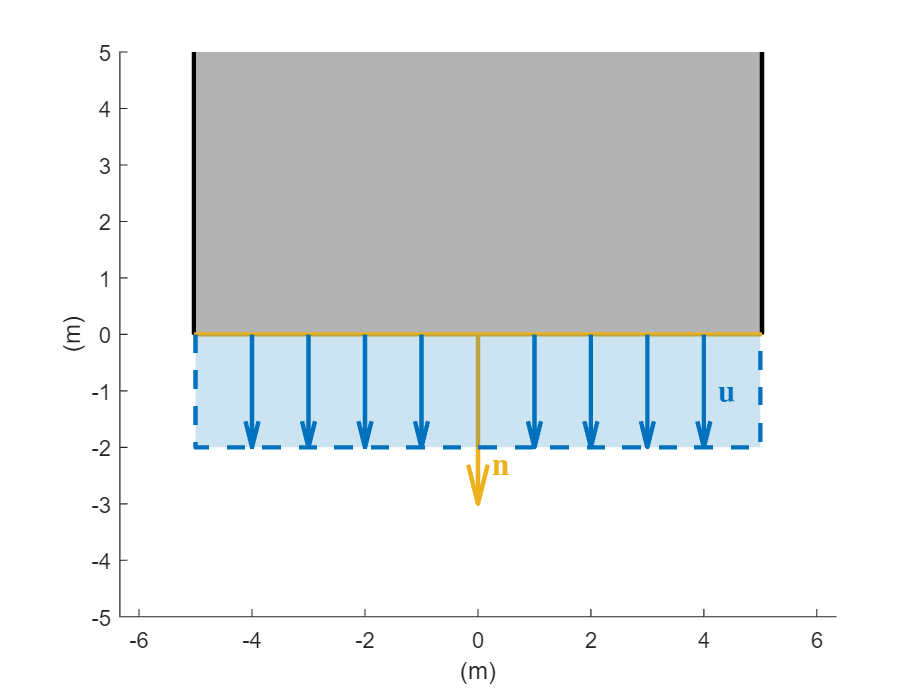

DirThrust = 0;
if     DirThrust == 1
    warning("The answer to this question is wrong")
    quiver(0,0,0,15, 0, "AutoScale","off","LineWidth",2,"MaxHeadSize",3.0,"Color",ax.ColorOrder(2,:))
    text(5.2,7.5, "F_{thrust}", "Color",ax.ColorOrder(2,:), "Interpreter","tex", "FontSize",14)

elseif DirThrust == 2
    warning("Try Again!")
else
    warning("Please select either Upward or Downward")
end
hold off
ylim([-15 115])


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV}_\text{Acceleration}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS}_\text{Thrust}
=
\Sigma {\bf F}$$


Because the rocket is in constant acceleration, we can decompose the acceleration term into two terms, the acceleration of the control volume and the acceleration within the control volue:


$$m(t)\frac{dy_g}{dt^2}+\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS
=
\Sigma {\bf F}$$


#### First term derivation

#### Second term derivation

** Demonstration**. From the Reynolds Transport theorem to mass conservation

The Reynolds Transport Theorem reads:


$$\underbrace{\frac{D}{Dt}\int_{CV} {\bf \phi}dV }_\text{(i)}
= 
\underbrace{\int_{CV}\frac{\partial{\bf \phi}}{\partial t} dV}_\text{(ii)}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n}){\bf\phi}dS}_\text{(iii)}$$


To derive the conservation of mass, we consider ${\bf \phi}=\rho{\bf u}$ the density.


$$\frac{D}{Dt}\int_{CV}\rho dV=\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho{\bf{u}} dS$$


From Newton's motion law we have:


$$\frac{D}{Dt}\int_{CV}\rho dV = \Sigma{\bf F}$$


Thus: 


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho{\bf{u}} dS = \Sigma{\bf F}$$


**Assumption: **


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV = 0$$


MomentumConservation = diff(diff(y,t),t) == ue*mdote/m(t) - g 
cond1 = y(0) == 0;Dy = diff(y, t); cond2 = Dy(0) == 0;
ySol(t) = dsolve(MomentumConservation, [cond1 cond2])
ySol = subs(ySol, {mdote, ue, m0, g}, {2180000/161, 9.81*281, 2950000, 9.81})
figure()
fplot(real(ySol), [0 161], "SeriesIndex",1, "LineWidth",2)
xlabel("Time (s)")
ylabel("Altitude (m)")
title("Apollo 11 Launch - Phase 1")

## Compare Results to Real Flight Log Data From Apollo 11 Mission

load ApolloFlightLog.mat

tiledlayout(3,1)
nexttile
plot(Apollo.t, Apollo.Altitude/1000, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Altitude (km)")
nexttile
plot(Apollo.t, Apollo.Velocity, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Velocity (m/s)")
nexttile
plot(Apollo.t, Apollo.Acceleration, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel('Acceleration (m/s^2)')
xlabel('Flight Time (s)')

 **Reflect**.  

## Causes of inacurracy

### Frictions Forces

[Insert control volume image with friction forces]

### Non-vertical flight path

In the previous section, we consider that the trust of the rocket was directed verticaly and therefore the flight path of the rocket should be purely vertical. However, the flight path of Apollo 11 was not directed directly verticaly. The mission consisted a getting the spacecraft into earth orbit for a couple of revolution before the start the translunar injection.

[Illustration incline climb]

Bla Blah Bla about the total trajectory

 
load Trajectory.mat
uif = uifigure();
gg = geoglobe(uif);
geoplot3(gg,Flight.Lat,Flight.Lon,Flight.El,'y','HeightReference','terrain', 'LineWidth',3)

## Improvement of the model

### Correction for rocket flight path angle

Show back the ODE from the vertical climb:

Ask question about how the acceleration term is modify:


$$\frac{\partial^2y(t)}{\partial t^2}=cos(\alpha(t))\frac{\dot{m_e}u_e}{m_o-\dot{m_e}t} - g$$


Plot Angle of ascend

alpha = @(t) interp1(Path.t, Path.Angle, t, 'pchip');
me    = 2180000/161;
m0    = 2950000;
Isp   = 281;
m     = @(t) m0 - me*t;
g     = 9.81;
ue    = Isp * g;

dudt = @(t,y) cosd(alpha(t))*me*ue/m(t)-g;
[tSol,uSol] = ode45(dudt, [0 161], 0);
plot(tSol,uSol)
dydt = @(t,y) interp1(tSol,uSol, t, 'pchip');
[tSol2,ySol] = ode45(dydt, [0 161], 0);
plot(tSol2, ySol)

### Adding the friction forces

#### Wind tunnel experimentation of Saturn V aerodynamic

Talk about wind tunnel?

Identify the parameter of the problem?

What are the repeating parameter?

Define the Mach Number:

Define friction coefficient:

#### New ODE

#### Define the atmosphere surrounding the rocket

Question about the equation of fluid statics?

Question about the density?

Question about equation of state?

Final equation

Present the ISA, ICAO etc atmosphere

Show the function

#### Solve ODE with friction

## Conclusion

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ax = DrawSaturn(varargin)
    % Define the axis:
    ax = axes;
    xlabel(ax, "(m)")
    ylabel(ax, "(m)")
    axis equal
    hold on

    % Define parameter
    Theta        = 0;
    PlotFootball = false;
    ColorHigh    = ax.ColorOrder(3,:);
    ColorCV      = false;
    ColorCSR     = false;
    ColorCSL     = false;
    ColorCSB     = false;
    dS           = false;
    Gravity      = false;

    % Read the varargin
    nargin = size(varargin,2);
    for n = 1:nargin
        if ( isstring(varargin{n}) | ischar(varargin{n}) )
            switch (varargin{n})
                case "Football"
                    PlotFootball = true;
                case "CV"
                    ColorCV = true;
                case "CSR"
                    ColorCSR = true;
                case "CSL"
                    ColorCSL = true;
                case "CSB"
                    ColorCSB = true;
                case "Color"
                    ColorHigh = varargin{n+1};
                case "Theta"
                    Theta = varargin{n+1};
                case "dS"
                    dS = true;
                case "Gravity"
                    Gravity = true;
            end
        end
    end

    % Plot rocket:
    xR = [ 0 5.0292 5.0292 3.302 3.302 1.9558 1.9558 1.143 1.143 0.635 0.635 0];
    yR = [ 0 0 63.9826 69.7484 81.838 91.313 95.2246 97.7646 101.6 102.87 110.49 111.76];
    if ~ColorCV
        patch( xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
        patch(-xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
    else
        patch( xR, yR, ColorHigh, "EdgeColor", "none")
        patch(-xR, yR, ColorHigh, "EdgeColor", "none")
    end

    % Right Control Surface
    if ~ColorCSR
        line( xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( xR(2:end),yR(2:end),"Color", ColorHigh, "LineStyle", "-", "LineWidth", 2)
    end

    % Left Control Surface
    if ~ColorCSL
        line( -xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line( -xR(2:end),yR(2:end),"Color", ColorHigh, "LineStyle", "-", "LineWidth", 2)
    end

    % Bottom Control Surface
    if ~ColorCSB
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    else
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", ColorHigh, "LineStyle", "-", "LineWidth", 2)
    end
    
    % Draw football field
    if PlotFootball
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1];
        patch(xF,yF, ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5, (i*10)*0.91, sprintf("%i 0", i-1), "Rotation",90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
                text(86.5, (i*10)*0.91, sprintf("%i 0", 11-i), "Rotation",-90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
            end
        end
        yF = yF + 10*0.9144;
        patch(xF,yF,ax.ColorOrder(7,:))
    end

    if ( ColorCSR & dS )
        q = quiver(xR(2), 40.0, 20, 0.0, 0, "AutoScale","off","LineWidth",2, "Color",ColorHigh, "MaxHeadSize",1.0);
        qPos = [q.XData; q.YData; 0.0];
        qDir = [q.UData; q.VData; 0.0];
        qPos = rotz(-Theta)*qPos;
        qDir = rotz(-Theta)*qDir;
        q.XData = qPos(1);
        q.YData = qPos(2);
        q.UData = qDir(1);
        q.VData = qDir(2);
        text(xR(2)+10, 44, "${\bf dS}$", "Interpreter","latex","HorizontalAlignment","center", "Color",ColorHigh, "Rotation",-Theta)
    end
    if ( ColorCSL & dS )
        q = quiver(-xR(2), 40.0, -20, 0.0, 0, "AutoScale","off","LineWidth",2, "Color",ColorHigh, "MaxHeadSize",1.0);
        qPos = [q.XData; q.YData; 0.0];
        qDir = [q.UData; q.VData; 0.0];
        qPos = rotz(-Theta)*qPos;
        qDir = rotz(-Theta)*qDir;
        q.XData = qPos(1);
        q.YData = qPos(2);
        q.UData = qDir(1);
        q.VData = qDir(2);
        text(-xR(2)-10, 44, "${\bf dS}$", "Interpreter","latex","HorizontalAlignment","center", "Color",ColorHigh, "Rotation",-Theta)
    end
    if ( ColorCSB & dS )
        q = quiver(0.0, 0.0, 0, -20.0, 0, "AutoScale","off","LineWidth",2, "Color",ColorHigh, "MaxHeadSize",1.0);
        qPos = [q.XData; q.YData; 0.0];
        qDir = [q.UData; q.VData; 0.0];
        qPos = rotz(-Theta)*qPos;
        qDir = rotz(-Theta)*qDir;
        q.XData = qPos(1);
        q.YData = qPos(2);
        q.UData = qDir(1);
        q.VData = qDir(2);
        text(4, -10, "${\bf dS}$", "Interpreter","latex","HorizontalAlignment","left", "Color",ColorHigh, "Rotation",-Theta)
    end

    if Gravity
        CG = [0.0; 40.0; 0.0];
        text(CG(1)-4, CG(2)-8, "${\bf g}$", "Interpreter","latex")
        CG = rotz(-Theta)*CG;
        scatter(CG(1), CG(2), 30, "filled", "k")
        quiver(CG(1), CG(2), 0.0, -20.0, 0, "AutoScale","off", "LineWidth",2,"Color","k", "MaxHeadSize",1.0)
    end
    
    
    if Theta ~= 0
        line([0 0], [-10 130], "LineStyle","-.", "Color", "k")
        hl = line([0 0], [0 yR(end)+20], "LineStyle", "-.","Color", "k");
        rotate(hl, [0 0 1], Theta, [0 yR(end) 0])
        i = linspace(0,Theta, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        plot(x,y, "k-")
        text(mean(x), mean(y)-4, "$\alpha$", "Interpreter", "latex", "FontSize",14)    
        child = allchild(ax);
        rotate(child, [0 0 1], -Theta, [0 0 0])
    end


    hold off
end


function rho = atmDensity(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq,0.0)} % Altitude in meter
        Standard string {mustBeMember(Standard,["ISA","ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % P = rho*R*T
    P = atmPressure(yq, Standard, R);
    T = atmTemp(yq, Standard);
    % Solution:
    rho = P ./ (R*T);
end

function T = atmTemp(yq, Standard)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
    end
    % Define the atmosphere:
    if     Standard == "ISA"
        y_Standard = [-610 11000 20000 32000 47000 51000 71000 84852];
        T_Standard = [19 -56.5 -56.5 -44.5 -2.5 -2.5 -58.5 -86.28]+273.15;
    elseif Standard == "ICAO"
        y_Standard = [0 11000 20000 32000];
        y_Standard = [15 -56.5 -56.5 -44.5]+273.15;
    end
    % Solution:
    T = interp1(y_Standard,T_Standard, yq, "linear");
end

function P = atmPressure(yq, Standard, R)
    arguments
        yq double {mustBeGreaterThanOrEqual(yq, 0.0)}
        Standard string {mustBeMember(Standard, ["ISA", "ICAO"])} = "ISA"
        R double {mustBePositive} = 287.0528 % Specific gas constant
    end
    % dP/dy = - P/(RT) g
    T = @(y) atmTemp(y, Standard);
    dPdy = @(y,P) -P/(R*T(y))*9.81;
    [ySol,PSol] = ode45(dPdy, [0.0 yq(end)], 101325);
    % Solution:
    P = interp1(ySol,PSol,yq);
end

function IntroRocket()
    figure()
    DrawSaturn("Football");
    title("Saturn V versus Football Field")
end

function IntroControlVolume(Item)
    figure()
    switch Item
        case 0
            DrawSaturn();
            title("Saturn V without highlight")
        case 1
            DrawSaturn("CV");
            title("Saturn V Control Volume")
        case 2
            DrawSaturn("CSR");
            title("Saturn V Right Control Surface")
        case 3
            DrawSaturn("CSL");
            title("Saturn V Left Control Surface")
        case 4
            DrawSaturn("CSB");
            title("Saturn V Bottom Control Surface")
    end
    ylim([-5 112])
end

function Score = SelectDirectionBottomControlSurface(Direction)
    figure()
    Score = 0;
    if Direction ==0
        ax = DrawSaturn("CSB");
        boxPos = ax.Position;
        boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
        boxPos(2) = 0.2;
        boxPos(4) = 0.25;
        txt = "Please selecte either Upward or Downward.";
        annotation("textbox", boxPos, "String", txt, "HorizontalAlignment","center", ...
            "VerticalAlignment","middle", "EdgeColor","none","Color","r")
    elseif Direction == 1
        ax = DrawSaturn("CSB");
        hold on 
        quiver(0,0,0,3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
        text(0.3,1.5,"${\bf dS}$","FontSize",14, "Interpreter","latex", "Color", ax.ColorOrder(3,:))
        boxPos = ax.Position;
        boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
        boxPos(2) = 0.2;
        boxPos(4) = 0.25;
        txt = "Wrong! Remember that by convention the normal vector to control surface are oriented towards the outised of the control volume.";
        annotation("textbox", boxPos, "String", txt, "HorizontalAlignment","center", ...
            "VerticalAlignment","middle", "EdgeColor","none","Color","r")
        hold off
    elseif Direction == 2
        ax = DrawSaturn("CSB");
        hold on 
        quiver(0,0,0,-3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
        text(0.3,-1.5,"${\bf dS}$","FontSize",14, "Interpreter","latex", "Color", ax.ColorOrder(3,:))
        boxPos = ax.Position;
        boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
        boxPos(2) = 0.6;
        boxPos(4) = 0.25;
        txt = "Good job! Remember that by convention the normal vector to control surface are oriented towards the outised of the control volume.";
        annotation("textbox", boxPos, "String", txt, "HorizontalAlignment","center", ...
            "VerticalAlignment","middle", "EdgeColor","none","Color","g")
        hold off
    end
    title("Control volume around the bottom of rocket")
    ylim([-5 5])
end

[⇦ Return to the navigation page](matlab: OpenOverview)